# PARCISER - Projet 6.1 

## Génération de données simulées d'une SER

Le but est ici de se familiariser avec les données susceptibles d'être en sortie de l'analyseur de réseau, lors d'une série d'acquisition de la chambre anéchoïque de l'ENSTA.

La fonction gen_synth.m m'a été gracieusement donnée par le Dr. Comblet. Elle nécessite de poser plusieurs variables :

map = [1:256 ; 1:256 ; ones(1,256)];  %Coordonnées des points brillants + amplitude
fmin = 3e9; fmax = 3.2e9; % fmin et fmax
th1 = 0; th2=20;  %angle min et max

nf = 2000; nth = 1000; %Nombre d'échantillons respectivement en angle, et en fréquence.

Ces variables sont posées... au pif. Ces valeurs sont à CHANGER (cf page 15 *Mesure de la SER*) 

Voyons ce que nous pouvons en faire.

sigc = gen_synth(map,fmin,fmax,nf,th1,th2,nth);

sigc est une matrice de nf lignes, et nth colonnes.

Représentons là : 

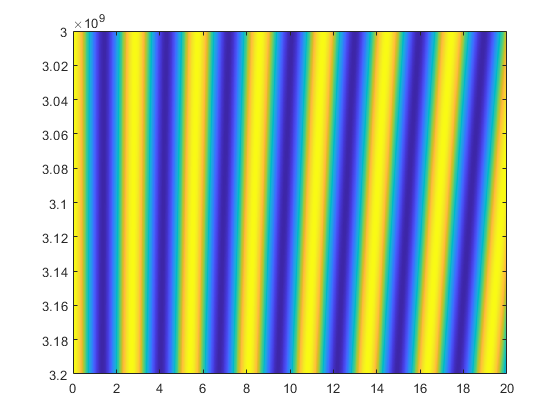

imagesc(linspace(th1,th2,nth),linspace(fmin,fmax,nf),abs(sigc).^2);  % Notons bien que là, j'ai mis les angles, puis les fréquences, sciemment.

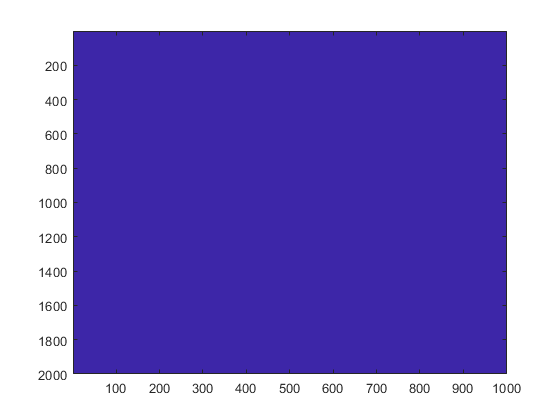

Xsig = ifft2(sigc);
figure;
imagesc(abs(Xsig).^2);